# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 5;
threshold = 0.6;

## Generate a random physical topology

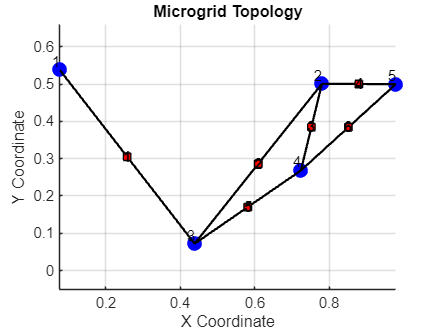

Coordinates of DGs:
    0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999

Adjacency Matrix:
     0     0     1     0     0
     0     0     1     1     1
     1     1     0     1     0
     0     1     1     0     1
     0     1     0     1     0

B_il Matrix:
     1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1



coords =     0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999


A_ij =      0     0     1     0     0
     0     0     1     1     1
     1     1     0     1     0
     0     1     1     0     1
     0     1     0     1     0


B_il =      1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
% R0 = 0.02;      % Resistance
% L0 = 0.01;      % Inductance
% C0 = 0.0022;    % Capacitance
% RL0 = 0.3;      % Load Resistance
% Y0 = 1/RL0;     % Load Conductance

R0 = 0.05;      % Resistance
L0 = 100e-6;      % Inductance
C0 = 10e-3;    % Capacitance
RL0 = 1;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


## Generate Random Set of Lines

% Initial parameter values for Lines
% Rl0 = 0.02;     % Line Resistance
% Ll0 = 0.01;     % Line Inductance

Rl0 = 0.1;     % Line Resistance
Ll0 = 100e-6;     % Line Inductance
numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 
 global DG Line B_il A_ij

## Co-Design Process

parameters


BarGamma = 1;    % Fixed value for gammaBar
isSoft = 1; % Set to 1 to avoid the hard graph constraint

pScalar = 1/(numOfDGs+numOfLines)

pScalar = 0.0909


% piVals = 0.2;
% plVals = 0.16;

piVals = pScalar*ones(1,numOfDGs);
plVals = pScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 

DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   0



% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

## 2. Global Controller Design

[DG,Line,statusGlobalController,gammaTildeVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)

DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusGlobalController = logical
   1


gammaTildeVal = 2.2255e-09

% DG{1}.K

Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

% minCost = 100000;
% 
% for pScalar = 0.01:0.01:10
% 
%     BarGamma = 5;    % Fixed value for gammaBar
%     isSoft = 1; % Set to 1 to avoid the hard graph constraint
% 
%     piVals = pScalar*ones(1,numOfDGs);
%     plVals = pScalar*ones(1,numOfLines);
% 
%     [DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 
%     [DG,Line,statusGlobalController,gammaTildeVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)
% 
%     cost = gammaTildeVal;
%     % cost = gammaTildeVal + 10000*(1-statusLocalController) + 10000*(1-statusGlobalController) 
% 
%     con1 = statusLocalController == 1;
%     con2 = statusGlobalController == 1;
%     % con3 = norm(DG{1}.K0) < 1000;
% 
%     if cost<minCost && con1 && con2
%         minCost = cost;
%         pStar = pScalar;
%     end
% 
% end
% 
% minCost
% pStar

Optimize pVals (Method 2: Use Matlab 'fmincon')

[piVals, plVals] = optimizeCodesignParameters(DG,Line,B_il)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      12    1.000000e+06    0.000e+00    0.000e+00

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

piVals =     0.2000    0.2000    0.2000    0.2000    0.2000


plVals =     0.1667    0.1667    0.1667    0.1667    0.1667    0.1667
